## ROS Frames in Mobile Robot Navigation

The following assignment investigates the evolution of the transform ${\tt odom}$ to ${\tt base\_link}$ according to odometry along with the corrections between ${\tt map} $and ${\tt odom}$ due to localization.

1) Restart the Gazebo Simulation with the ${\tt world}$ environment and launch the navigation node.

Set the initial pose of the robot in RViz according to the robot pose in the Gazebo simulation using the button "2D Pose Estimate".

2) Restart the global Matlab ROS node with ${\tt rosinit}
$

3) Retrieve the ROS transformation tree and check whether the frames ${\tt map, odom}$ and $ {\tt base\_link} $ are available.

4) Instantiate subscribers for the topics ${\tt' /move\_base\_simple/goal'}$ and${\tt '/clicked\_point'}$. The topic ${\tt '/clicked\_point'} $ contains the most recent published point in RVIZ. If the "Publish Point" button is not active in toolbar, select the "+" button and add the publish point to tools.

5) Receive the published point from the topic ${\tt '/clicked\_point'}$ and create a rated while loop at a rate of 10 Hz. (The while loop spans until the end of task 7)


while                   % while loop start

6) Within the loop, transform the published point message into the frames ${\tt map, odom}$ and ${\tt base\_link}$. Subsequently, convert the ${\tt PointStamped}$ message into its ordinary components with the helper function ${\tt PointStampedMsg2Point} $.

7) Plot of x- and y- components of the published point w.r.t. the three different frames while setting ${\tt hold\; on}$ to superimpose the points of every loop cycle. Observe the evolution of the published point w.r.t. the three frames as the robot is moving.


end % while loop end

8) Publish a point in RVIZ in the ${\tt map}$ frame and start the navigation in RVIZ by setting a navigation goal. 

9) Repeat the experiment but this time publish the point in the ${\tt odom}$ frame. Select the frame in RViz under Displays -> Global Options -> Fixed Frame.

10) Repeat the experiment but this time publish the point in the $ {\tt base\_link}$ frame.

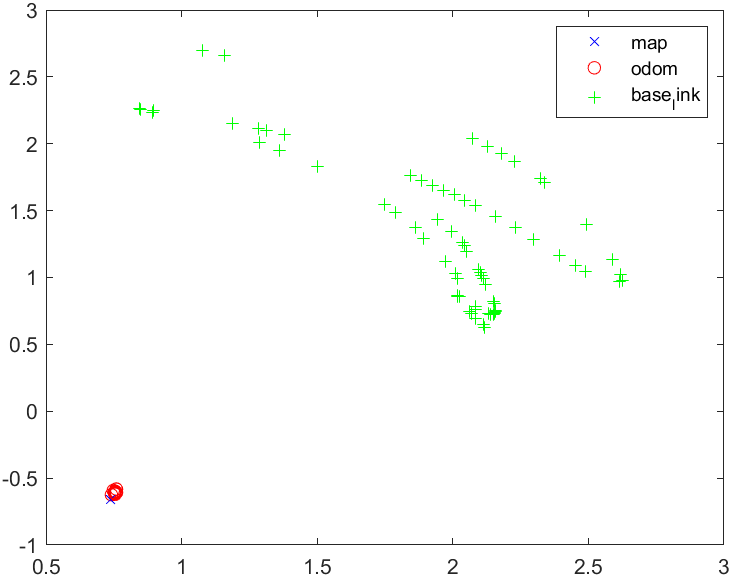

## Point Cloud Mapping with Known Poses

11) Inspect ROS topics and check for a topic ${\tt /camera/depth/points}$. This topic contains message of type ${\tt sensor\_msgs/PointCloud2}$ that contains the laser scan range data as a point cloud in the laser base frame ${\tt /camera\_rgb\_optical\_frame}$.

 12) Inspect the particular topic ${\tt /camera/depth/points}$ and inspect information about the message type ${\tt sensor\_msgs/PointCloud2}$.

13) Instantiate a subscriber for the topic ${\tt /camera/depth/points}$ and receive a message. Check the field ${\tt Header.FrameId}$ to figure out the frame to which the point cloud data is associated.

14) Inspect the the available frames in the ROS transformation tree and check for the ${\tt /map}$ and ${\tt /camera\_rgb\_optical\_frame}$ frames.

15) Verify that the transform between ${\tt /camera\_rgb\_optical\_frame}$ and ${\tt /map}$ is available with ${\tt canTransform}$.

16) Transform the point cloud message from its current frame to the ${\tt /map}$ frame with ${\tt transform}$.

17) Extract the x-y-z-coordinates of the point cloud in the ${\tt /map}$ frame with ${\tt readXYZ}$. Convert the x-y-z array to a ${\tt pointCloud}$ object and randomly downsample the point cloud to 1% of the original one. Finally. visualize the x-y-z coordinates in a figure with ${\tt pcshow}$.

18) Create a rated while loop such that it receives, transforms and downsamples the laser point cloud w.r.t. the global static $ {\tt map}$ frame and accumulates the latest downsampled point cloud in an array in every loop cycle. To access the x-y-z coordinates of the points from a ${\tt pointCloud}$ object, use its ${\tt Location}$ attribute. Visualize the mapping process using the ${\tt pcplayer}$. For this, initialize it before the loop using ${\tt player = pcplayer([-5,5],[-5,5],[0,2])}$. In every loop cycle update player with the current accumulated point cloud using the method ${\tt view}$. Run the loop and set a navigation goal for the robot in RViz.

19) Improve the accuracy of mapping by applying the transform w.r.t. the time stamp of the point cloud message.

20) Investigate the quality of the superimposed point clouds if you transform the point cloud to the ${\tt odom}$ rather than the ${\tt map}$ frame.

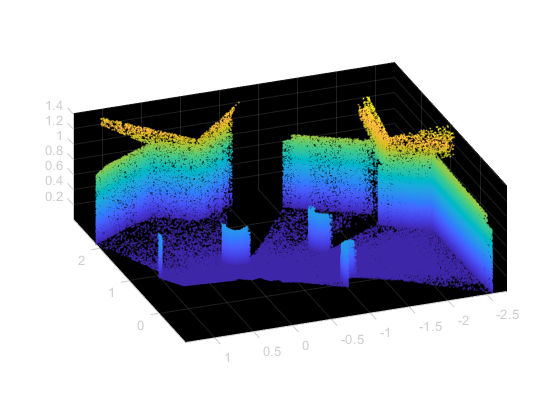

## Scan Matching with the Normal Distribution Transform

Create a loop for processing the scans and mapping the area. The laser scans are processed in pairs. Define the previous scan as reference scan and the latest scan as current scan. The two scans are then passed to the scan matching algorithm and the relative pose between the two scans is computed with ${\tt matchScans}$.

21) Instantiate a subscriber ${\tt scanSub}$ for the laser scan topic ${\tt /scan} $ and assign the received scan message to the variable ${\tt referenceScanMsg}$.

22) Extract the scan angles ${\tt  scanAngles}$ from the message with ${\tt readScanAngles}$. Notice that the ${\tt scanAngles}$ remain the same throughout the loop as only the range readings change but noot the angular resolution of the scanner. Initialize the $\texttt{relativePose}$ with $\texttt{[0 0 0]}$.

23) Within a while loop, receive the current scan message $ {\tt currentScanMsg}$.

24) Extract the ranges ${\tt refScanRanges}$ and ${\tt currScanRanges}$ from the ${\tt Ranges}$ field of the scan messages. 

25) Determine the ${\tt relativePose}$ between the two scans with ${\tt matchScans}$. In each loop iteration, provide the $\texttt{relativePose}$ as $\texttt{'InitialPose'}$ to the $\texttt{matchScans}$ function. Skip the following steps, if the scan matching result is poor which is indicated by a low matching score.

26) Determine the true range readings that are below the maximum range reading.

27) Convert the current scan readings in range from polar into Cartesian coordinates ${\tt scanX}$, ${\tt scanY}$ with ${\tt pol2cart}$.

28) Determine the homogeneous transform of the relative pose and integrate with the absolute transform by postmultiplication of the two homogeneous transformation matrices.

29) Apply the absolute transform to the Cartesian coordinates of the scan points ${\tt scanX}$, ${\tt scanY}$.

30)  Plot the transformed scan points while setting ${\tt hold\; on}$ to superimpose the scans of every loop cycle.

31) The current scan message becomes the reference scan message of the next iteration of the loop.

32) Run the loop and set a navigation goal for the robot in RViz. Inspect the created laser scan matching map.

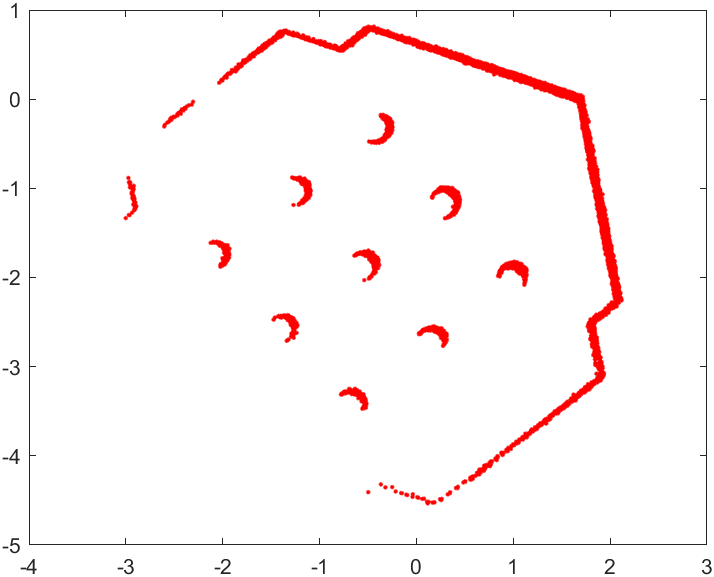

## Occupancy Grid Mapping (Optional)

33) Instantiate a probabilistic occupancy grid of object class ${\tt OccupancyGrid}$ centered at $$(7.5, 7.5)$$ meter.

34) Convert the homogeneous transformation matrix ${\tt absoluteTform} $back into an ordinary pose vector ${\tt absolutePose}$ in terms of  $$[x \ y \ \theta]$$ with$ {\tt tform2tvec}$ and ${\tt tform2eul}$.

35) Within the while loop insert the laser range readings with the estimated absolute pose into the occupancy grid with ${\tt insertRay}$.

36) Visualize the occupancy grid map with ${\tt show}$.

37) Vary the maximum linear and angular robot velocity, when moving in the map, and observe the quality of the created occupancy grid map. To set a maximum velocity for the turtlebot use the rqt reconfigure gui:

The maximum linear and angular velocity can be changed in the DWA tab.

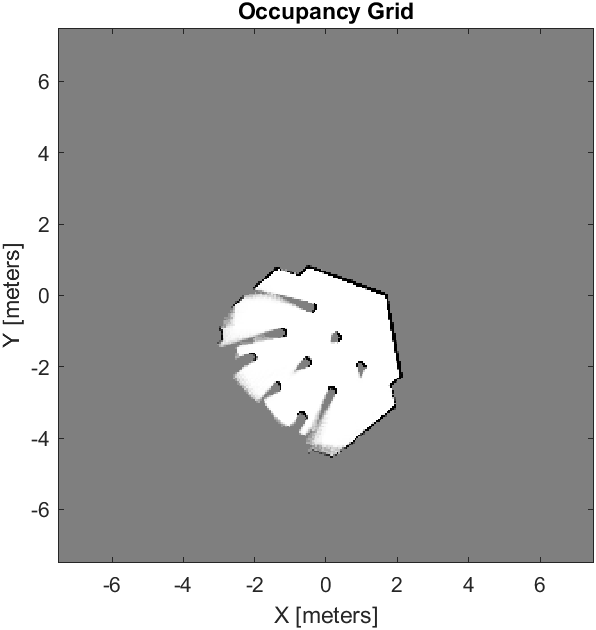

# Helper Functions

function [ x, y, z ] = PointStampedMsg2Point( pointMsg )
    % convert odometry message to vector
    x=pointMsg.Point.X;
    y=pointMsg.Point.Y;
    z=pointMsg.Point.Z;
end